11.3（`离散拉普拉斯算子矩阵`）实时脚本

由张志涌编写、修改于 2023.1。

L形域编号及delsq计算离散拉普拉斯

clear
m = 5

m = 5

L = numgrid('L',2*m+1)

L =      0     0     0     0     0     0     0     0     0     0     0
     0     1     5     9    13    17    21    30    39    48     0
     0     2     6    10    14    18    22    31    40    49     0
     0     3     7    11    15    19    23    32    41    50     0
     0     4     8    12    16    20    24    33    42    51     0
     0     0     0     0     0     0    25    34    43    52     0
     0     0     0     0     0     0    26    35    44    53     0
     0     0     0     0     0     0    27    36    45    54     0
     0     0     0     0     0     0    28    37    46    55     0
     0     0     0     0     0     0    29    38    47    56     0


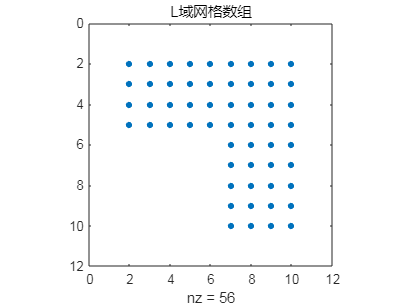

spy(L),title('L域网格数组')

As=-delsq(numgrid('L',2*m+1))

As =    (1,1)       -4
   (2,1)        1
   (5,1)        1
   (1,2)        1
   (2,2)       -4
   (3,2)        1
   (6,2)        1
   (2,3)        1
   (3,3)       -4
   (4,3)        1
   (7,3)        1
   (3,4)        1
   (4,4)       -4
   (8,4)        1
   (1,5)        1
   (5,5)       -4
   (6,5)        1
   (9,5)        1
   (2,6)        1
   (5,6)        1
   (6,6)       -4
   (7,6)        1
  (10,6)        1
   (3,7)        1
   (6,7)        1
   (7,7)       -4
   (8,7)        1
  (11,7)        1
   (4,8)        1
   (7,8)        1
   (8,8)       -4
  (12,8)        1
   (5,9)        1
   (9,9)       -4
  (10,9)        1
  (13,9)        1
   (6,10)       1
   (9,10)       1
  (10,10)      -4
  (11,10)       1
  (14,10)       1
   (7,11)       1
  (10,11)       1
  (11,11)      -4
  (12,11)       1
  (15,11)       1
   (8,12)       1
  (11,12)       1
  (12,12)      -4
  (16,12)       1
   (9,13)       1
  (13,13)      -4
  (14,13)       1
  (17,13)       1
  (10,14)       1
  (13

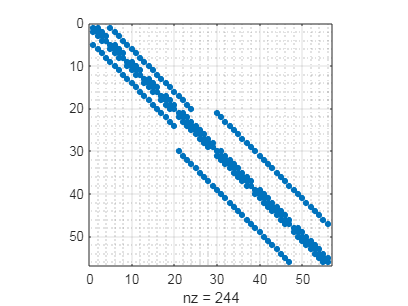

spy(As),grid on,grid minor

A = full(As);A16=A(1:16,1:16)

A16 =     -4     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     1     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     1    -4     0     0     0     1     0     0     0     0     0     0     0     0
     1     0     0     0    -4     1     0     0     1     0     0     0     0     0     0     0
     0     1     0     0     1    -4     1     0     0     1     0     0     0     0     0     0
     0     0     1     0     0     1    -4     1     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     1    -4     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0    -4     1     0     0     1     0     0     0
     0     0     0     0     0     1     0     0     1    -4     1     0     0     1     0     0


disp('*******************')

*******************


del命令与离散拉普拉斯

h = 1/20;
[x,y] = meshgrid(-1:h:1);
u = x.^2 + y.^2

u =     2.0000    1.9025    1.8100    1.7225    1.6400    1.5625    1.4900    1.4225    1.3600    1.3025    1.2500    1.2025    1.1600    1.1225    1.0900    1.0625    1.0400    1.0225    1.0100    1.0025    1.0000    1.0025    1.0100    1.0225    1.0400    1.0625    1.0900    1.1225    1.1600    1.2025    1.2500    1.3025    1.3600    1.4225    1.4900    1.5625    1.6400    1.7225    1.8100    1.9025    2.0000
    1.9025    1.8050    1.7125    1.6250    1.5425    1.4650    1.3925    1.3250    1.2625    1.2050    1.1525    1.1050    1.0625    1.0250    0.9925    0.9650    0.9425    0.9250    0.9125    0.9050    0.9025    0.9050    0.9125    0.9250    0.9425    0.9650    0.9925    1.0250    1.0625    1.1050    1.1525    1.2050    1.2625    1.3250    1.3925    1.4650    1.5425    1.6250    1.7125    1.8050    1.9025
    1.8100    1.7125    1.6200    1.5325    1.4500    1.3725    1.3000    1.2325    1.1700    1.1125    1.0600    1.0125    0.9700    0.9325    0.9000    0.8725    0.8500    

d = (4/h^2) * del2(u)

d =     4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000
    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000
    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    4.0000    

disp('*******************')

*******************


`inregion实施编号`

xv = [0  0  1  1 -1 -1 0];
yv = [0 -1 -1  1  1  0 0];
[x,y] = meshgrid(-1:h:1);
[in,on] = inregion(x,y,xv,yv);
p = find(in-on);
n = length(p);
L = zeros(size(x));
L(p) = 1:n;
A = -delsq(L)

A =    (1,1)       -4
   (2,1)        1
  (20,1)        1
   (1,2)        1
   (2,2)       -4
   (3,2)        1
  (21,2)        1
   (2,3)        1
   (3,3)       -4
   (4,3)        1
  (22,3)        1
   (3,4)        1
   (4,4)       -4
   (5,4)        1
  (23,4)        1
   (4,5)        1
   (5,5)       -4
   (6,5)        1
  (24,5)        1
   (5,6)        1
   (6,6)       -4
   (7,6)        1
  (25,6)        1
   (6,7)        1
   (7,7)       -4
   (8,7)        1
  (26,7)        1
   (7,8)        1
   (8,8)       -4
   (9,8)        1
  (27,8)        1
   (8,9)        1
   (9,9)       -4
  (10,9)        1
  (28,9)        1
   (9,10)       1
  (10,10)      -4
  (11,10)       1
  (29,10)       1
  (10,11)       1
  (11,11)      -4
  (12,11)       1
  (30,11)       1
  (11,12)       1
  (12,12)      -4
  (13,12)       1
  (31,12)       1
  (12,13)       1
  (13,13)      -4
  (14,13)       1
  (32,13)       1
  (13,14)       1
  (14,14)      -4
  (15,14)       1
  (33,14)       1
  (14,

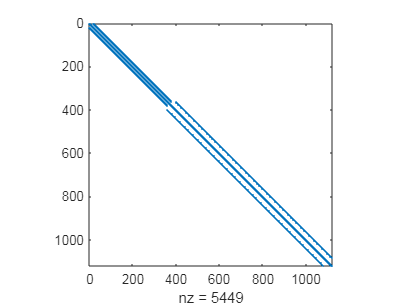

spy(A)